# CDS ERA5 Data Download and Plot

This script...

## **1 Setting up Python env**

Follow the instructions in cds_setup.txt

Then restart matlab, uncomment the code below and run it. Make sure to set the base path to where your virtual environment is located on your computer.

If you have opted to not use virtual environment then use pyenv to ensure that your MATLAB is running the correction version of python which has the cds library installed.

% Path to your virtual environment's base directory
venv_base_path = '/Users/tris/Documents/MSc/';

% Command to activate the virtual environment and run a Python command
% Note: this should be the path to the env with csd installed
command = ['cd ' venv_base_path ' && source .venv/bin/activate && python -c "import sys; print(sys.executable)"'];

% Execute the command
[status, cmdout] = system(command);

% Display the output to check the correct python path has been used 
disp(cmdout);

/Users/tris/Documents/MSc/.venv/bin/python



% Set the Python environment in MATLAB to the correct version
pyenv('Version', '/Users/tris/Documents/MSc/.venv/bin/python');
pyenv

ans =   PythonEnvironment with properties:

          Version: "3.9"
       Executable: "/Users/tris/Documents/MSc/.venv/bin/python"
          Library: "/Library/Developer/CommandLineTools/Library/Frameworks/Python3.framework/Versions/3.9/lib/libpython3.9.dylib"
             Home: "/Users/tris/Documents/MSc/.venv"
           Status: NotLoaded
    ExecutionMode: InProcess


## 2 **ERA5 Data - **Single Level

### **Downloading the data**

Now that the Python environment in MATLAB is correctly set, specify the parameters that you want to download and run the code below.

Check previous requests: [https://cds.climate.copernicus.eu/cdsapp#!/yourrequests](https://cds.climate.copernicus.eu/cdsapp#!/yourrequests)

% % Import the cdsapi module
% cdsapi = py.importlib.import_module('cdsapi');
% 
% % Create a Client instance
% c = cdsapi.Client();
% 
% params = py.dict(pyargs( ...
%     'product_type', 'reanalysis', ...
%     'variable', py.list({'mean_direction_of_total_swell', 'mean_direction_of_wind_waves', 'mean_period_of_total_swell', ...
%                          'mean_period_of_wind_waves', 'mean_wave_direction', 'mean_wave_period', ...
%                          'significant_height_of_combined_wind_waves_and_swell', 'significant_height_of_total_swell', ...
%                          'significant_height_of_wind_waves', 'wave_spectral_kurtosis'}), ...
%     'year', '2022', ...
%     'month', '07', ...
%     'day', '20', ...
%     'time', py.list({'00:00', '01:00', '02:00', '03:00', '04:00', '05:00', '06:00', '07:00', '08:00', ...
%                      '09:00', '10:00', '11:00', '12:00', '13:00', '14:00', '15:00', '16:00', '17:00', ...
%                      '18:00', '19:00', '20:00', '21:00', '22:00', '23:00'}), ...
%     'area', py.list([-55, -10, -70, 10]), ...
%     'format', 'netcdf' ...
%     ));
% 
% % Define the output file name
% date = "20220720";
% output_file = 'ERA5-single-2Dws_'+date+".nc";
% 
% c.retrieve('reanalysis-era5-single-levels', params, output_file);

### **Load in the parameters**

%% Get Parameters of the complete 
filepath = "/Users/tris/Documents/MATLAB/MSc/ERA5-single-2Dws_20220720.nc";

info_single = ncinfo(filepath);

%data storing 2D wave spectra with 24 directions (starting from 7.5N
%direction towards) and 30 frequencie starting from 0.0345 Hz;
lon_single = ncread(filepath,'longitude');
lat_single = ncread(filepath,'latitude');
time_single = ncread(filepath,'time');


% Mean Wave Direction (θ): The average direction from which the swell waves are coming.
% Mean Wave Period (T): The average period of the swell waves.

mean_direction_total_swell = ncread(filepath,'mdts'); %121 31 48 = lon lat time
mean_period_total_swell = ncread(filepath,'mpts');
significant_wave_height_total_swell = ncread(filepath,'shts');

mean_direction_wind_waves = ncread(filepath,'mdww');
mean_period_wind_waves = ncread(filepath,'mpww');
significant_wave_height_wind_waves = ncread(filepath,'shww');

mean_wave_direction = ncread(filepath,'mwd');
mean_wave_period = ncread(filepath,'mwp');
significant_wave_height = ncread(filepath,'swh');

time_index_single = 7;

### Plot the imported data

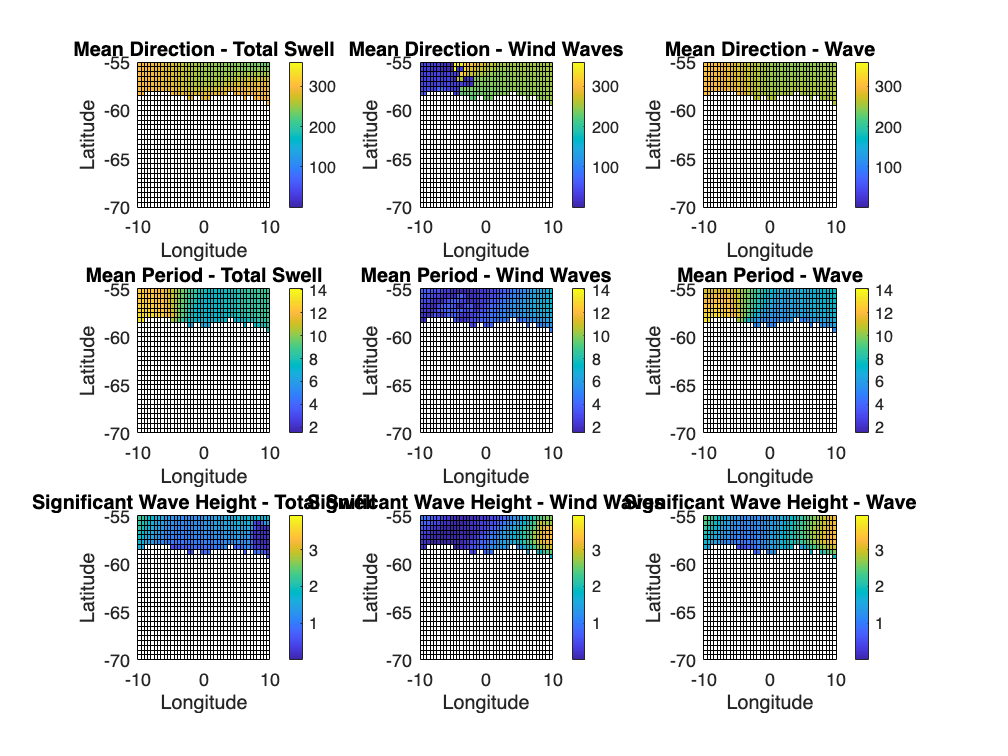

% Plot the Lat-Long x-y grid 
[lonGrid_single, latGrid_single] = meshgrid(lon_single,lat_single);


% Create a 2x2 grid of subplots
figure;

% WAVE DIRECTION
minVal = min([
    min(mean_direction_total_swell(:));
    min(mean_direction_wind_waves(:));
    min(mean_wave_direction(:));
]);

% maxVal = max([
%     max(mean_direction_total_swell(:));
%     max(mean_direction_wind_waves(:));
%     max(mean_wave_direction(:));
% ]);
maxVal = 360;

% First subplot
subplot(3, 3, 1); % 2 rows, 2 columns, 1st subplot
pcolor(lonGrid_single, latGrid_single, mean_direction_total_swell(:,:,time_index_single)'); % Note: transpose 'test' to match the grid orientation
clim([minVal maxVal]);
colorbar; % Add a colorbar to show the data scale
xlabel('Longitude');
ylabel('Latitude');
title('Mean Direction - Total Swell');

% Second subplot
subplot(3, 3, 2); % 2 rows, 2 columns, 1st subplot
pcolor(lonGrid_single, latGrid_single, mean_direction_wind_waves(:,:,time_index_single)'); % Note: transpose 'test' to match the grid orientation
clim([minVal maxVal]);
colorbar; % Add a colorbar to show the data scale
xlabel('Longitude');
ylabel('Latitude');
title('Mean Direction - Wind Waves');

% Third subplot
subplot(3, 3, 3); % 2 rows, 2 columns, 1st subplot
pcolor(lonGrid_single, latGrid_single, mean_wave_direction(:,:,time_index_single)'); % Note: transpose 'test' to match the grid orientation
clim([minVal maxVal]);
colorbar; % Add a colorbar to show the data scale
xlabel('Longitude');
ylabel('Latitude');
title('Mean Direction - Wave');

% WAVE PERIOD
minVal = min([
    min(mean_period_total_swell(:));
    min(mean_period_wind_waves(:));
    min(mean_wave_period(:));
]);
maxVal = max([
    max(mean_period_total_swell(:));
    max(mean_period_wind_waves(:));
    max(mean_wave_period(:));
]); 

% Fourth subplot
subplot(3, 3, 4); % 2 rows, 2 columns, 1st subplot
pcolor(lonGrid_single, latGrid_single, mean_period_total_swell(:,:,time_index_single)'); % Note: transpose 'test' to match the grid orientation
clim([minVal maxVal]);
colorbar; % Add a colorbar to show the data scale
xlabel('Longitude');
ylabel('Latitude');
title('Mean Period - Total Swell');

% Fifth subplot
subplot(3, 3, 5); % 2 rows, 2 columns, 1st subplot
pcolor(lonGrid_single, latGrid_single, mean_period_wind_waves(:,:,time_index_single)'); % Note: transpose 'test' to match the grid orientation
clim([minVal maxVal]);
colorbar; % Add a colorbar to show the data scale
xlabel('Longitude');
ylabel('Latitude');
title('Mean Period - Wind Waves');

% Sixth subplot
subplot(3, 3, 6); % 2 rows, 2 columns, 1st subplot
pcolor(lonGrid_single, latGrid_single, mean_wave_period(:,:,time_index_single)'); % Note: transpose 'test' to match the grid orientation
clim([minVal maxVal]);
colorbar; % Add a colorbar to show the data scale
xlabel('Longitude');
ylabel('Latitude');
title('Mean Period - Wave');

% SIGNIFICANT WAVE HEIGHT
minVal = min([ ...
    min(significant_wave_height_total_swell(:));
    min(significant_wave_height_wind_waves(:));
    min(significant_wave_height(:)) ...
]);
maxVal = max([
    max(significant_wave_height_total_swell(:));
    max(significant_wave_height_wind_waves(:));
    max(significant_wave_height(:))
]);
% Seventh subplot
subplot(3, 3, 7); % 2 rows, 2 columns, 1st subplot
pcolor(lonGrid_single, latGrid_single, significant_wave_height_total_swell(:,:,time_index_single)'); % Note: transpose 'test' to match the grid orientation
clim([minVal maxVal]);
colorbar; % Add a colorbar to show the data scale
xlabel('Longitude');
ylabel('Latitude');
title('Significant Wave Height - Total Swell');

% Eighth subplot
subplot(3, 3, 8); % 2 rows, 2 columns, 1st subplot
pcolor(lonGrid_single, latGrid_single, significant_wave_height_wind_waves(:,:,time_index_single)'); % Note: transpose 'test' to match the grid orientation
clim([minVal maxVal]);
colorbar; % Add a colorbar to show the data scale
xlabel('Longitude');
ylabel('Latitude');
title('Significant Wave Height - Wind Waves');

% Ninth subplot
subplot(3, 3, 9); % 2 rows, 2 columns, 1st subplot
pcolor(lonGrid_single, latGrid_single, significant_wave_height(:,:,time_index_single)'); % Note: transpose 'test' to match the grid orientation
clim([minVal maxVal]);
colorbar; % Add a colorbar to show the data scale
xlabel('Longitude');
ylabel('Latitude');
title('Significant Wave Height - Wave');

## **3 ERA5 Data - Complete**

### **Downloading the data**

Now that the Python environment in MATLAB is correctly set, specify the parameters that you want to download and run the code below.

Check previous requests: [https://cds.climate.copernicus.eu/cdsapp#!/yourrequests](https://cds.climate.copernicus.eu/cdsapp#!/yourrequests)

% Import the cdsapi module
cdsapi = py.importlib.import_module('cdsapi');

% Create a Client instance
c = cdsapi.Client();

% Define the parameters for the retrieve function
params = py.dict(pyargs( ...
    'class', 'ea', ...
    'date', '2022-07-22', ...
    'direction', '1/2/3/4/5/6/7/8/9/10/11/12/13/14/15/16/17/18/19/20/21/22/23/24', ...
    'domain', 'g', ...
    'expver', '1', ...
    'frequency', '1/2/3/4/5/6/7/8/9/10/11/12/13/14/15/16/17/18/19/20/21/22/23/24/25/26/27/28/29/30', ...
    'param', '251.140', ...
    'stream', 'wave', ...
    'time', '00:00:00/01:00:00/02:00:00/03:00:00/04:00:00/05:00:00/06:00:00/07:00:00/08:00:00/09:00:00/10:00:00/11:00:00/12:00:00/13:00:00/14:00:00/15:00:00/16:00:00/17:00:00/18:00:00/19:00:00/20:00:00/21:00:00/22:00:00/23:00:00', ...
    'type', 'an', ...
    'area', py.list([-55, -10, -70, 10]), ...  % North, West, South, East
    'grid', '1.0/1.0', ... % Latitude/longitude
    'format', 'netcdf' ... % Output format
    ));


% Define the output file name
date = "20220722";
output_file = 'ERA5-2Dws_'+date+".nc";

% Call the retrieve method
c.retrieve('reanalysis-era5-complete', params, output_file);

Error using api>_api (line 481)
Python Error: Exception: Not Found

Error in api>retrieve (line 381)

### **Load in the parameters**

%% Get Parameters of the complete 
filepath = "/Users/tris/Documents/MATLAB/MSc/ERA5-2Dws_20220720.nc";

% Store file info in MATLAB struct
info = ncinfo(filepath);

% Get attributes
lon=ncread(filepath,'longitude');
lat=ncread(filepath,'latitude');
time = ncread(filepath,'time');
dir=ncread(filepath,'direction');
d2fd=ncread(filepath,'d2fd');
d2fd=double(d2fd); % Usually dimensions are: lon lat dir frq time

% freq ERA5 according to https://confluence.ecmwf.int/display/CKB/ERA5%3A+data+documentation
freq_bins = zeros(size(d2fd,4),1);
freq_bins(1)=0.03453;
for i=2:length(freq_bins)
freq_bins(i) = freq_bins(i-1)*1.1;
end

### **Define Points of Interest**

These are the points in the single level data (from step 2) that we are interested in view the spectrum of (in step 4).

latitude_of_interest = -58;
longitude_of_interest = -5;
time_of_interest = time_single(time_index_single); % this should be the same as the time index chosen in step 2 for all plots.

### **Plot the 2D wave spectra**

Note when working with the data: the dimensions are usually in the order lon lat time OR lon lat dir frq time. This can be checked by using ncinfo to get a structure of the file and then looking at the "Dimensions" field.

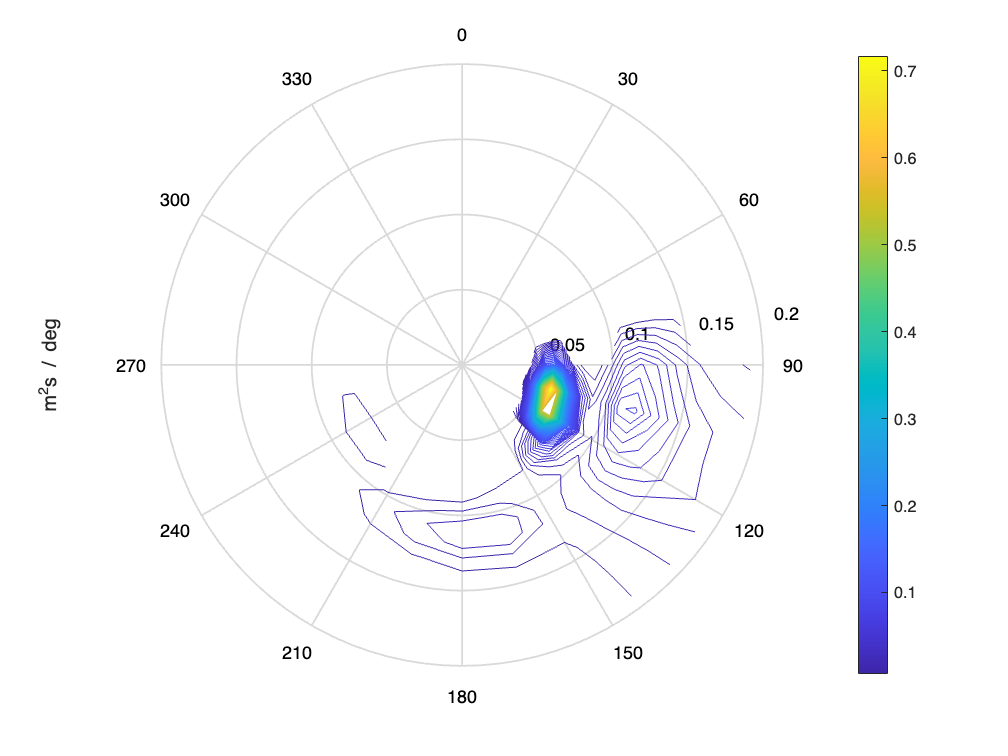

% Find the slice that matches what we are plotting in the single level data
% in step 2.
time_position_match = find(time == time_of_interest);
lat_position_match = find(lat == latitude_of_interest);
lon_position_match = find(lon == longitude_of_interest);

% Plot the 2D spectra
figure;
sp(:,:)=10.^d2fd(lon_position_match,lat_position_match,:,:,time_position_match);
PolarContour(sp, freq_bins, 0.2);

### Calculate the parameters

% direction integration values according to the ERA5 documentation
direction_bins = (7.5: 15: 352.5)/180*pi; % From ERA5 documentation

#### Significant Height

% Calculate the wave spectrum for all time
spectrum_all_time = zeros(size(d2fd,5),size(d2fd,3),size(d2fd,4)); % dimensions t direc freq
for t = 1:size(d2fd,5)
    d2fd_match(:,:) = d2fd(lon_position_match,lat_position_match,:,:,t); % Dimensions are: direction,frequency
    spectrum_all_time(t,:,:) = 10.^d2fd_match;
    spectrum_all_time(isnan(spectrum_all_time))=0; % Otherwise all values are just N
end

% Calculate the 0th order moments (m_n) [Eq.8]
m0_derived_all_time = trapz(direction_bins,trapz(freq_bins,1*spectrum_all_time,3),2); %[Eq.8], dimension 2,3 = direc,freq

% Calculate the significant wave height (Hs) [Eq.4]
Hs_derived_all_time = 4*sqrt(m0_derived_all_time); 

#### Mean wave period

% Calculate the -1st order moments (m_n)
m_neg1_derived_all_time = zeros(size(d2fd,5),1);
for t = 1:size(d2fd,5)
    spectrum(:,:) = spectrum_all_time(t,:,:);
    m_neg1_derived_all_time(t,1) = trapz(direction_bins,trapz(freq_bins,(1/freq_bins).*spectrum,2),1); %[Eq.8]
end

% Calculate the mean wave period (Tm) [Eq.5]
Tm_derived_all_time = m_neg1_derived_all_time./m0_derived_all_time; % [Eq.5]

#### Mean wave direction

% Calculate the angular moments [Eq.9&10]
for t = 1:size(d2fd,5)
    spectrum(:,:) = spectrum_all_time(t,:,:); % dimenstions: direc, freq
    a1(t) = trapz(freq_bins,trapz(direction_bins,cos(direction_bins)'.*spectrum,1),2); %[Eq.9]
    test = sin(direction_bins)'.*spectrum_all_time;
    b1(t) = trapz(freq_bins,trapz(direction_bins,sin(direction_bins)'.*spectrum,1),2); %[Eq.10]
end

% Calculate the mean Direction of the wave
direction_derived_all_time = atand(b1./a1); %[Eq.6]

## 4 Comparing the Mean calculations

This is to compare the values of the mean wave period, height and direction in the single level data to values computed from the complete data 2D wave spectrum. 

This code uses formulas from *"Evolution of wave directional properties in sea ice" - *Alberto Alberello a,∗, Emilian I. Părău a, Qingxiang Liu b,c, Francesca De Santi d 

% ERA5 significant wave height at the same point
% time_position_match_single = find(time_single == time_single(7));
lat_position_match_single = find(lat_single == latitude_of_interest);
lon_position_match_single = find(lon_single == longitude_of_interest);
% Hs_era5 = significant_wave_height(lon_position_match_single,lat_position_match_single,time_position_match);

Hs_era5_all_time(:) = significant_wave_height(lon_position_match_single,lat_position_match_single,:);
Hs_derived_all_time = Hs_derived_all_time';

Direction

% Derived values in Step 3.
dirc_derived = 360+direction_derived_all_time(7);
% ERA5 significant wave height at the same point
direc_single = mean_wave_direction(lat_position_match,lon_position_match,time_position_match);